clear 
clc

t = [3.08,2.43,2.08,1.85,1.52,1.28];
u = [194,177,151,126,106,71];
i = [0.12,0.12,0.11,0.11,0.1,0.1];
n = [1385,1258,1070,890,747,499];
p = u.*i

p =    23.2800   21.2400   16.6100   13.8600   10.6000    7.1000


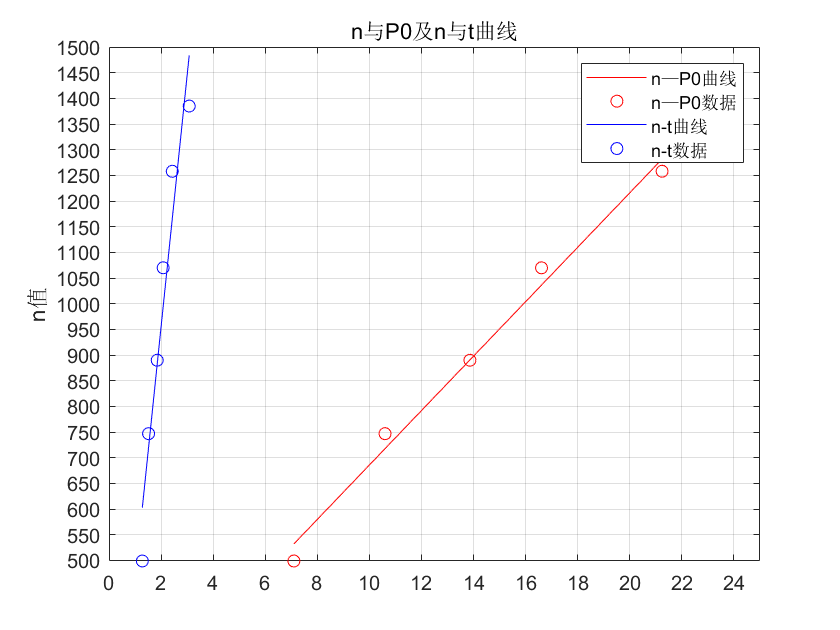


% plot(p,n,'ro-')
% title('n—P0曲线')
% xlabel('P0值')
% ylabel('n值')

pn=polyfit(p,n,1);
yy=polyval(pn,p);
plot(p,yy,'r-',p,n,'ro')

hold on

pn = polyfit(t,n,1);
yy = polyval(pn,t);
plot(t,yy,'b-',t,n,'bo')
title('n与P0及n与t曲线')
ylabel('n值')

hold on
% x = [0 1 2 3 4 5 10 15 16 17 18 19 20 22 26]
% y = [1000 1000 1000 1000 1000 1000 1000 1000 1000 1000 1000 1000 1000 1000 1000]
% plot(x,y,'m-')
legend('n—P0曲线','n—P0数据','n-t曲线','n-t数据')

grid on
set(gca,'xtick',0:2:30);
set(gca,'ytick',0:50:1500);


hold off

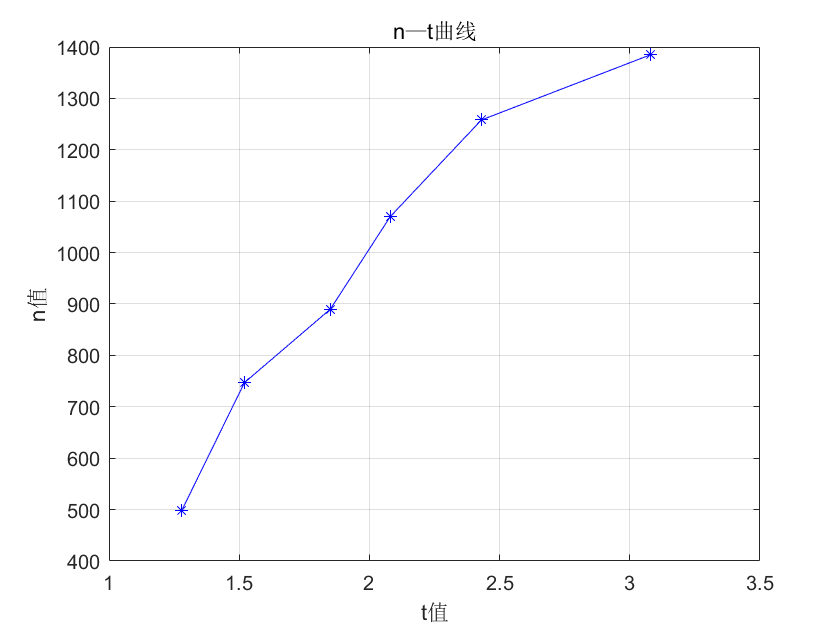

plot(t,n,'b*-')
title('n—t曲线')
xlabel('t值')
ylabel('n值'),grid on




clear
clc
i_1 = [0.16,0.15,0.14,0.13,0.12,0.11,0.10,0.09,0.07]

i_1 =     0.1600    0.1500    0.1400    0.1300    0.1200    0.1100    0.1000    0.0900    0.0700


n_1 = [1598 1599 1601 1601 1602 1603 1605 1607 1608]

n_1 =         1598        1599        1601        1601        1602        1603        1605        1607        1608


n_1 = n_1(end:-1:1)

n_1 =         1608        1607        1605        1603        1602        1601        1601        1599        1598



i_2 = [0.14 0.141 0.143 0.146 0.149 0.15 0.155 0.16 0.165]

i_2 =     0.1400    0.1410    0.1430    0.1460    0.1490    0.1500    0.1550    0.1600    0.1650


n_2 = [1628 1660 1689 1726 1760 1785 1818 1855 1867]

n_2 =         1628        1660        1689        1726        1760        1785        1818        1855        1867


n_2 = n_2(end:-1:1)

n_2 =         1867        1855        1818        1785        1760        1726        1689        1660        1628



i_3 = [0.1 0.105 0.11 0.115 0.12 0.125 0.13 0.135 0.14 0.145 0.15 0.16]

i_3 =     0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1600


n_3 = [1402 1184 877 592 210 -183 -402 -714 -981 -1286 -1500 -1942]

n_3 =         1402        1184         877         592         210        -183        -402        -714        -981       -1286       -1500       -1942


% n_3 = n_3(end:-1:1)


i_4 = [0.06 0.05 0.04 0.03 0.02 0.01]

i_4 =     0.0600    0.0500    0.0400    0.0300    0.0200    0.0100


n_4 = [1053 950 796 641 430 273]

n_4 =         1053         950         796         641         430         273


n_4 = n_4(end:-1:1)

n_4 =          273         430         641         796         950        1053




i_5 = [0.1 0.09 0.08 0.07 0.06 0.05 0.04 0.03]

i_5 =     0.1000    0.0900    0.0800    0.0700    0.0600    0.0500    0.0400    0.0300


n_5 = [990 885 792 688 590 504 414 330]

n_5 =    990   885   792   688   590   504   414   330


n_5 = n_5(end:-1:1)

n_5 =    330   414   504   590   688   792   885   990


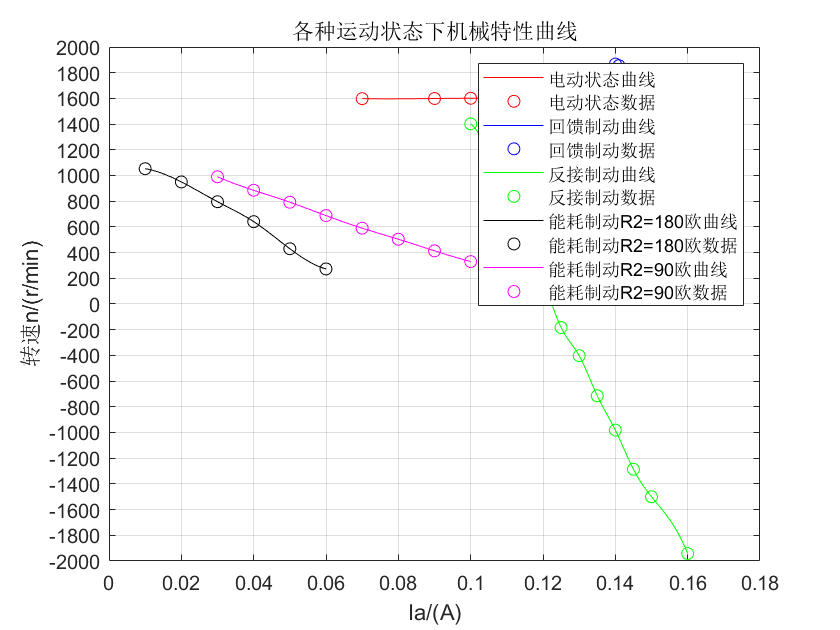



ii1 = linspace(0.07,0.16);
nn1 = spline(i_1,n_1,ii1);

ii2 = linspace(0.14,0.16);
nn2 = spline(i_2,n_2,ii2);

ii3 = linspace(0.10,0.16);
nn3 = spline(i_3,n_3,ii3);

ii4 = linspace(0.01,0.06);
nn4 = spline(i_4,n_4,ii4);

ii5 = linspace(0.03,0.10);
nn5 = spline(i_5,n_5,ii5);




plot(ii1,nn1,'r',i_1,n_1,'ro')
hold on
plot(ii2,nn2,'b',i_2,n_2,'bo')
hold on
plot(ii3,nn3,'g',i_3,n_3,'go')
hold on 
plot(ii4,nn4,'k',i_4,n_4,'ko')
hold on
plot(ii5,nn5,'m',i_5,n_5,'mo')

grid on
title('各种运动状态下机械特性曲线')
xlabel('Ia/(A)')
ylabel('转速n/(r/min)')
legend('电动状态曲线','电动状态数据','回馈制动曲线','回馈制动数据','反接制动曲线','反接制动数据','能耗制动R2=180欧曲线','能耗制动R2=180欧数据','能耗制动R2=90欧曲线','能耗制动R2=90欧数据')

grid on
set(gca,'xtick',0:0.02:0.18);
set(gca,'ytick',-2000:200:2000);